# [Solution] SVD Example: Image compression

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

## Solution to Exercise (a): Understanding singular vectors

The exercise of this tutorial is designed to make students familiar with reading and understanding MATLAB documentation. If you didn't read the documentation for `fft` (Fast Fourier transform), please read it through to the end. At the last part of the documentation, it reads that `Y = fft(X)` gives the result:


$$Y(k) = \sum_{j = 1}^n X(j) e^{-2 \pi \mathrm{i} (j-1) (k-1) /n} \, ,$$


where $n$ is the length of `X` and `Y`.

First load the image data, and the obtain the singluar values and vectors.

clear

M = imread('Gwanghwamun.jpg');
M = double(M); % convert data type: uint8 -> double
M = sum(M,3); % sum over the 3rd dim.
[U,S,V] = svd(M);
S = diag(S); % take the diagonal part

Choose the singular vectors for the 10 largest singular values and the 10 smallest singular values.

N = 10;
% indices of singular values/vectors
ids = [(1:N), numel(S)+(1-N:0)];

% selected singular values/vectors
Sp = S(ids);
Up = U(:,ids);
Vp = V(:,ids);

Then apply `fft`.

Uk = fft(Up);
Vk = fft(Vp);
whos Uk % it's complex!

  Name         Size             Bytes  Class     Attributes

  Uk        2730x20            873600  double    complex   



Each row of `Uk` or `Vk` corresponds to a wave number $k$.

For easier analysis, we reorganize the Fourier component `Uk` into the sine and cosine bases, such that


$$Y_{\sin} (k) = \sum_{j=1}^n X(j) \sin \left( \frac{2 \pi  (j-1)(k-1)}{n} \right),$$



$$Y_{\cos} (k) = \sum_{j=1}^n X(j) \cos \left( \frac{2 \pi  (j-1)(k-1)}{n} \right),$$


for $k \leq (n+1)/2$.

% Y_sin (k)
Uk_sin = -imag(Uk(1:floor((size(Uk,1)+1)/2),:));
% Y_cos (k)
Uk_cos =  real(Uk(1:floor((size(Uk,1)+1)/2),:));

whos Uk_sin Uk_cos % now real

  Name           Size             Bytes  Class     Attributes

  Uk_cos      1365x20            218400  double              
  Uk_sin      1365x20            218400  double              




% likewise for Vk
Vk_sin = -imag(Vk(1:floor((size(Vk,1)+1)/2),:));
Vk_cos =  real(Vk(1:floor((size(Vk,1)+1)/2),:));

Let's plot the Fourier components.

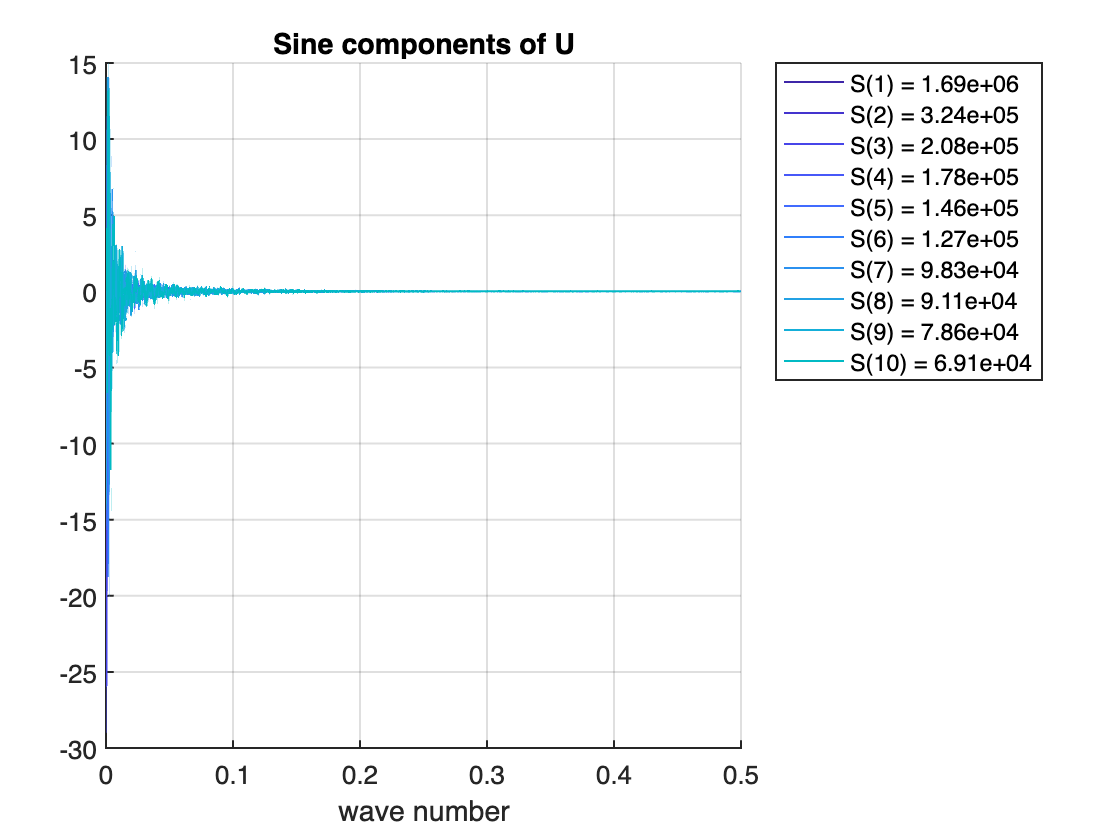

cmap = parula(size(Uk_sin,2)); % color for lines
ks = ((1:size(Uk_sin,1)).'-1)/size(Uk,1); % wave number

% for sine components of U, largest singular values
figure;
legs = cell(1,N); % texts for legend
hold on;
for it = (1:N)
    plot(ks,Uk_sin(:,it),'LineWidth',1,'Color',cmap(it,:));
    legs{it} = ['S(',sprintf('%i',ids(it)),') = ', ...
        sprintf('%.3g',Sp(it))];
    % show associated singular values
end
hold off;
set(gca,'LineWidth',1,'FontSize',13)
title('Sine components of U'); % add title
xlabel('wave number'); % add x-label
grid on; % turn on grid line
legend(legs,'Location','bestoutside');

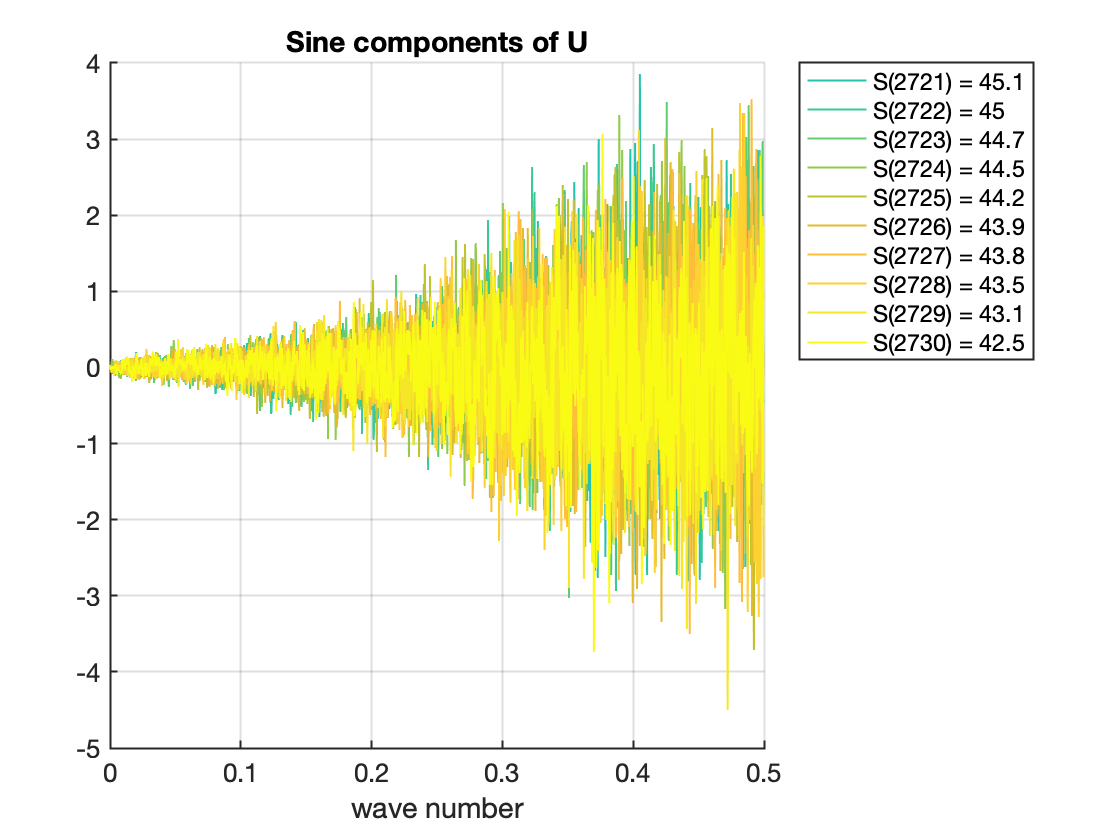

% for sine components of U, smallest singular values
figure;
legs = cell(1,N); % texts for legend
hold on;
for it = (N+1:2*N)
    plot(ks,Uk_sin(:,it),'LineWidth',1,'Color',cmap(it,:));
    legs{it-N} = ['S(',sprintf('%i',ids(it)),') = ', ...
        sprintf('%.3g',Sp(it))];
end
hold off;
set(gca,'LineWidth',1,'FontSize',13)
title('Sine components of U'); % add title
xlabel('wave number'); % add x-label
grid on; % turn on grid line
legend(legs,'Location','bestoutside');

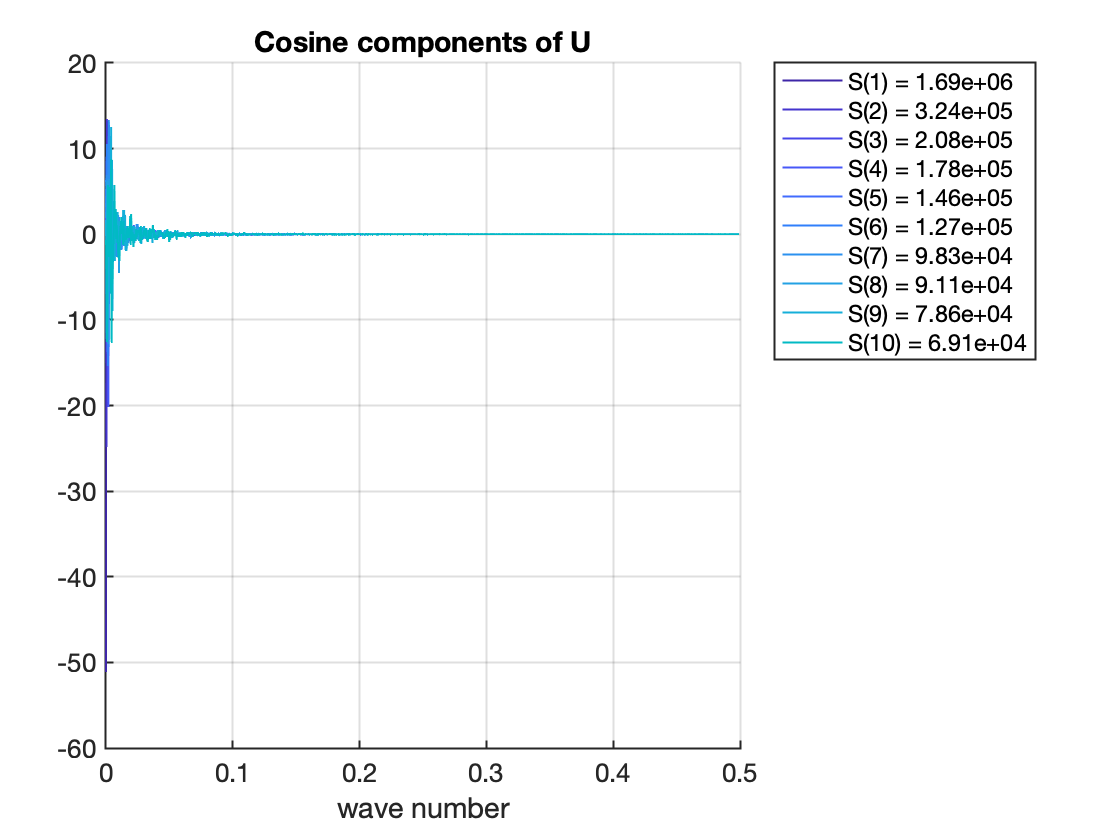

% for cosine components of U, largest singular values
figure;
legs = cell(1,N); % texts for legend
hold on;
for it = (1:N)
    plot(ks,Uk_cos(:,it),'LineWidth',1,'Color',cmap(it,:));
    legs{it} = ['S(',sprintf('%i',ids(it)),') = ', ...
        sprintf('%.3g',Sp(it))];
end
hold off;
set(gca,'LineWidth',1,'FontSize',13)
title('Cosine components of U'); % add title
xlabel('wave number'); % add x-label
grid on; % turn on grid line
legend(legs,'Location','bestoutside');

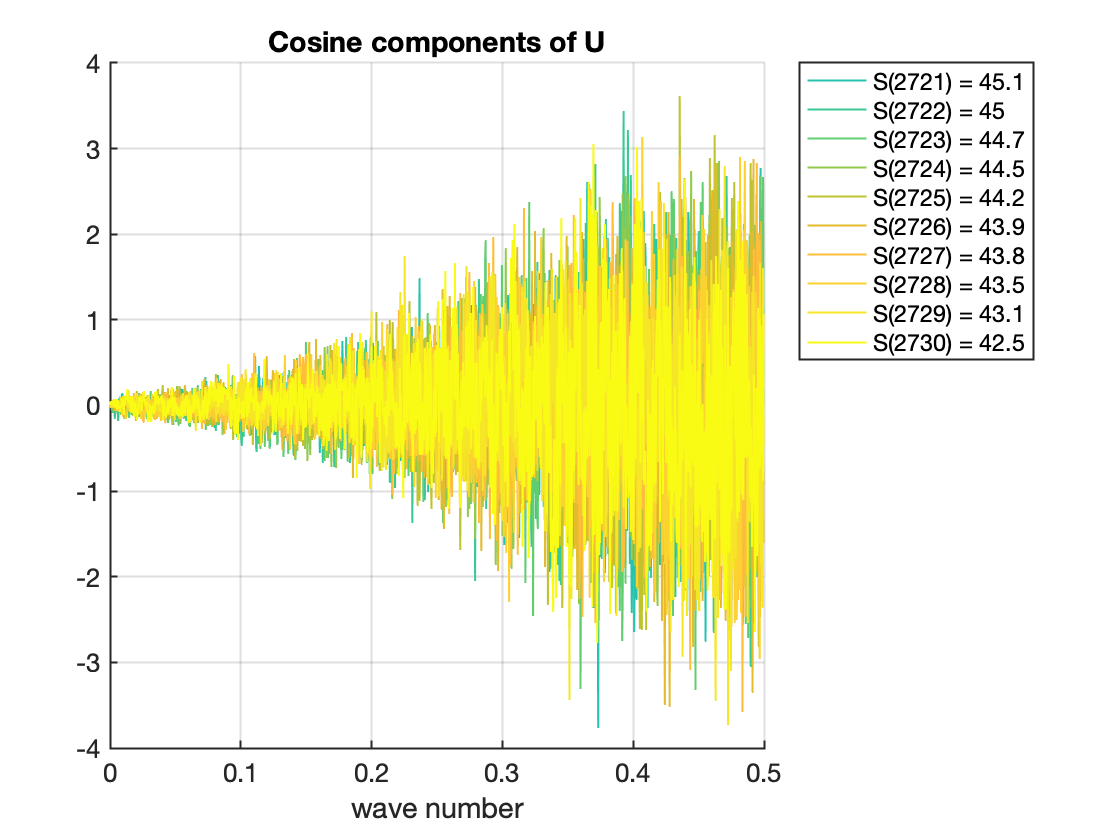

% for cosine components of U, smallest singular values
figure;
legs = cell(1,N); % texts for legend
hold on;
for it = (N+1:2*N)
    plot(ks,Uk_cos(:,it),'LineWidth',1,'Color',cmap(it,:));
    legs{it-N} = ['S(',sprintf('%i',ids(it)),') = ', ...
        sprintf('%.3g',Sp(it))];
end
hold off;
set(gca,'LineWidth',1,'FontSize',13)
title('Cosine components of U'); % add title
xlabel('wave number'); % add x-label
grid on; % turn on grid line
legend(legs,'Location','bestoutside');

Plot also similarly for the Fourier components of V.

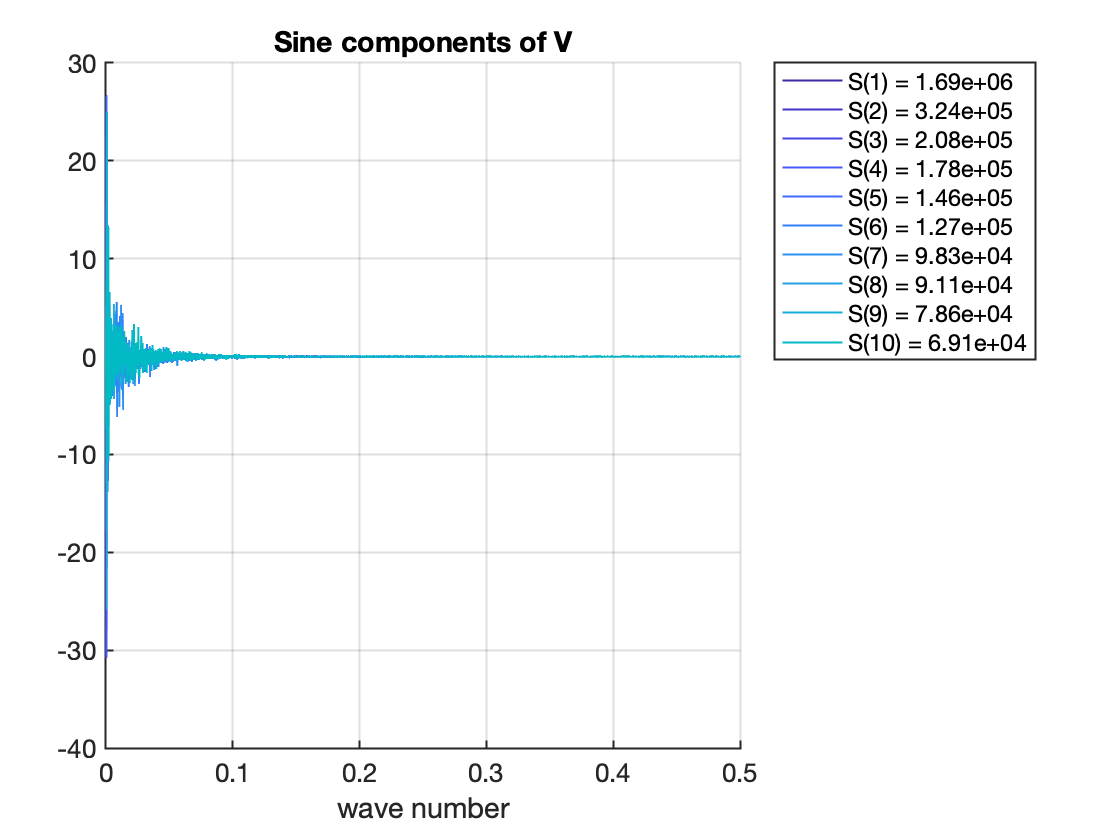

cmap = parula(size(Vk_sin,2)); % color for lines
ks = ((1:size(Vk_sin,1)).'-1)/size(Vk,1); % wave number

% for sine components of U, largest singular values
figure;
legs = cell(1,N); % texts for legend
hold on;
for it = (1:N)
    plot(ks,Vk_sin(:,it),'LineWidth',1,'Color',cmap(it,:));
    legs{it} = ['S(',sprintf('%i',ids(it)),') = ', ...
        sprintf('%.3g',Sp(it))];
end
hold off;
set(gca,'LineWidth',1,'FontSize',13)
title('Sine components of V'); % add title
xlabel('wave number'); % add x-label
grid on; % turn on grid line
legend(legs,'Location','bestoutside');

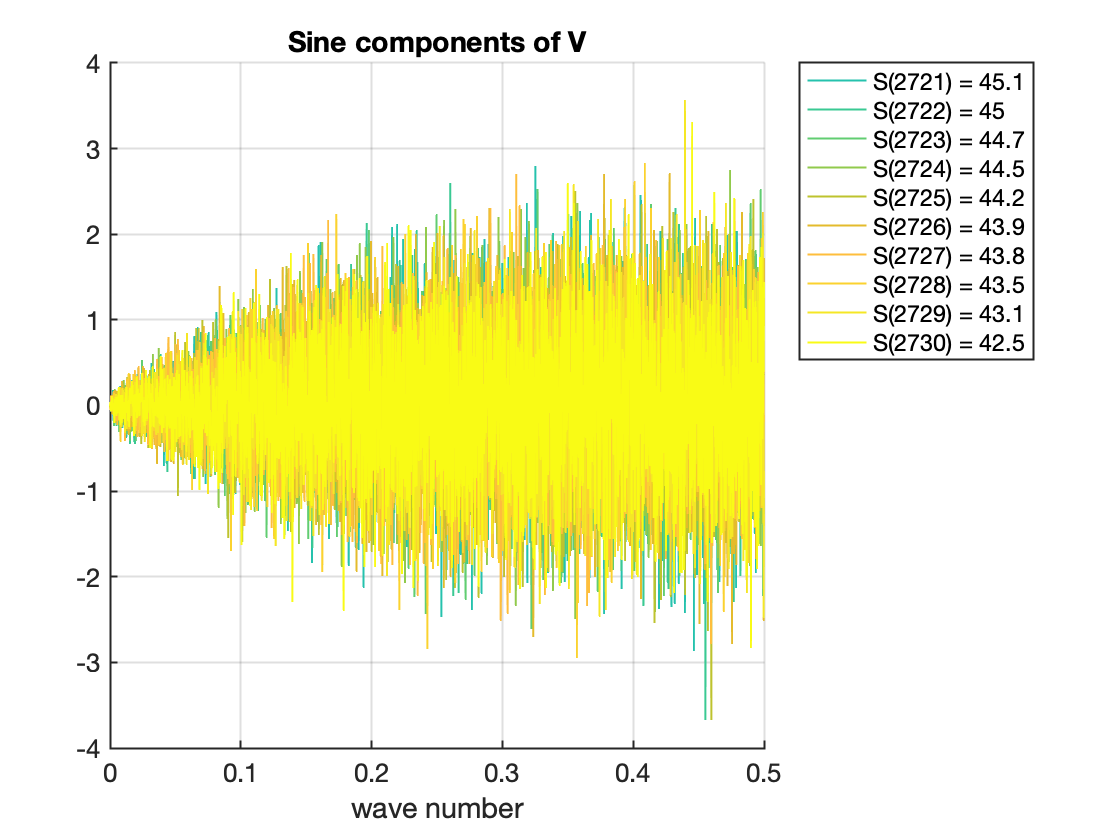

% for sine components of V, smallest singular values
figure;
legs = cell(1,N); % texts for legend
hold on;
for it = (N+1:2*N)
    plot(ks,Vk_sin(:,it),'LineWidth',1,'Color',cmap(it,:));
    legs{it-N} = ['S(',sprintf('%i',ids(it)),') = ', ...
        sprintf('%.3g',Sp(it))];
end
hold off;
set(gca,'LineWidth',1,'FontSize',13)
title('Sine components of V'); % add title
xlabel('wave number'); % add x-label
grid on; % turn on grid line
legend(legs,'Location','bestoutside');

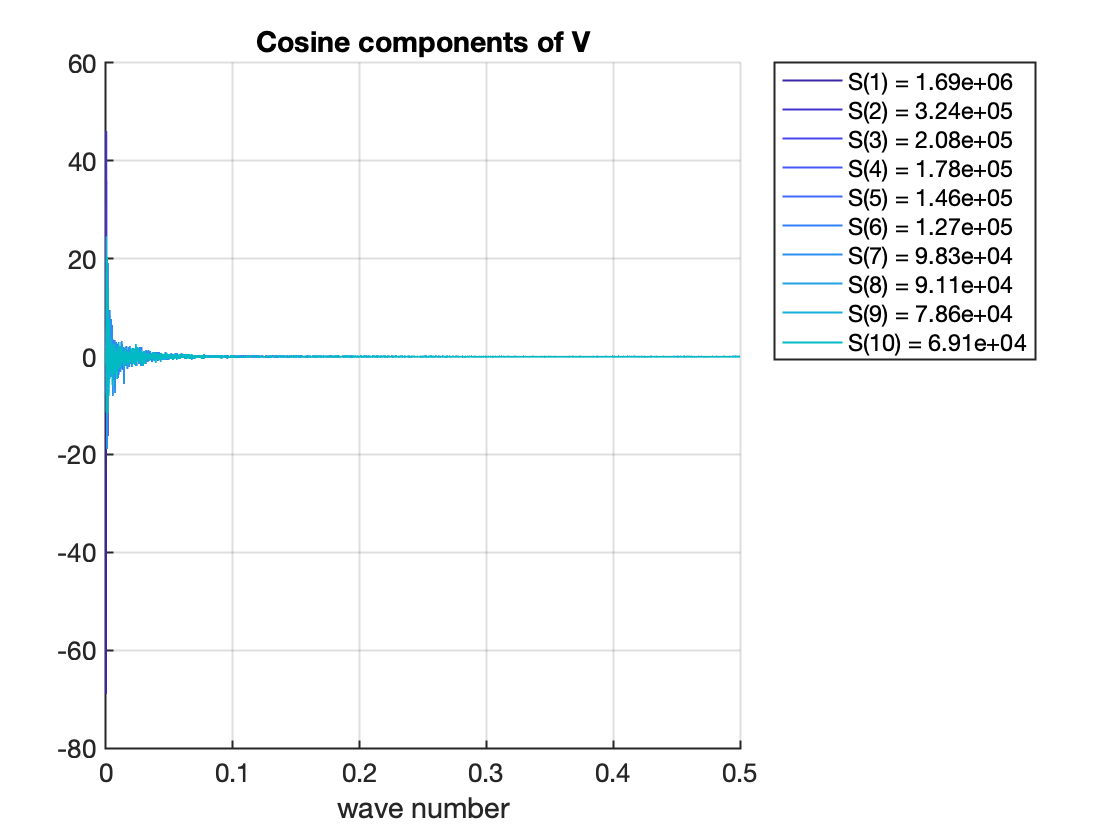

% for cosine components of V, largest singular values
figure;
legs = cell(1,N); % texts for legend
hold on;
for it = (1:N)
    plot(ks,Vk_cos(:,it),'LineWidth',1,'Color',cmap(it,:));
    legs{it} = ['S(',sprintf('%i',ids(it)),') = ', ...
        sprintf('%.3g',Sp(it))];
end
hold off;
set(gca,'LineWidth',1,'FontSize',13)
title('Cosine components of V'); % add title
xlabel('wave number'); % add x-label
grid on; % turn on grid line
legend(legs,'Location','bestoutside');

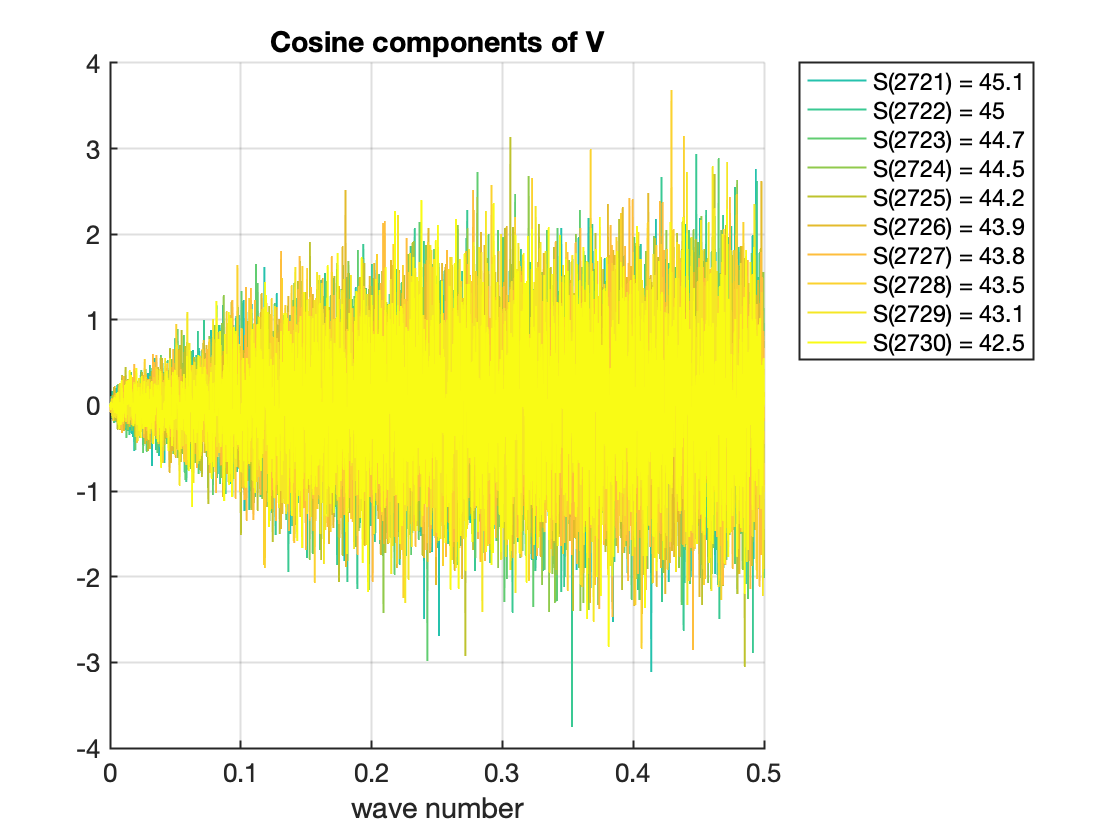

% for cosine components of V, smallest singular values
figure;
legs = cell(1,N); % texts for legend
hold on;
for it = (N+1:2*N)
    plot(ks,Vk_cos(:,it),'LineWidth',1,'Color',cmap(it,:));
    legs{it-N} = ['S(',sprintf('%i',ids(it)),') = ', ...
        sprintf('%.3g',Sp(it))];
end
hold off;
set(gca,'LineWidth',1,'FontSize',13)
title('Cosine components of V'); % add title
xlabel('wave number'); % add x-label
grid on; % turn on grid line
legend(legs,'Location','bestoutside');

## What do we learn from it?

The Fourier components of the singular vectors, both in `U` and `V`, show consistent behaviors. For the largest singular values, the Fourier components are larger at small wave numbers, and show fast decay as wave number increases. 

On the other hand, for the smallest singular values, the Fourier components look like white noise, since they are spread over the whole range of wave numbers.

This observation is consistent with the idea of **renormalization group (RG)**, which will be covered later in the lecture course. The spirit of RG is that more important information is associated with long length scale or low frequency scale, while the fluctuations at short length scale or high frequency scale become irrelevant at low temperatures.